%      _
%      | +5V
%     / \
%  R1/   \RG
%   *  VG *
%    \   /
%   R2\ /R3
%      *
%      |
%      V GND

GF=2.1;
%Eric
% R1=351.4; % ohms
% R2=328.8; % ohms
% R3=347.8; % ohms
%Aiden
R1=325+20.4;
R2=328;
R3=326+20.4;
RG=350; % ohms
Vin=4.94; % V
r_max=8388607;
r_min=-8388608;
V_max=80/1000; %V
V_min=-80/1000; %V
syms epsilon dR dV F r
% Change in resistance in terms of epsilon
RR=solve(GF==(dR/RG)/epsilon,dR)

$$RR = 735\,\epsilon$$

% Change in voltage in terms of epsilon
VV=solve(subs(Vin*(R3)/(R3+dR+RG)-Vin*R2/(R1+R2)==dV,dR,RR),dV)

$$VV = \frac{7526007558545343}{4398046511104\,\left(735\,\epsilon +\frac{3482}{5}\right)}-\frac{3116}{1295}$$

% Steps per volt
SperV=((V_max-V_min)/(r_max-r_min))^-1

SperV = 1.0486e+08

% A rough factor based on value at .015 strain
vpa(solve(.015==subs(VV,epsilon,.015)*SperV/F,F))

$$ans = 89189610.05607629199975139185271$$

% Exact value of epsilon based on r
g=simplify(solve(r==VV*SperV,epsilon))

$$g = -\frac{2266471696846290944\,r-12133297756796792344671825}{64651283713228800\,\left(37\,r+9335321775\right)}$$

X=linspace(r_min,r_max,1000)

X = 	1.0e+06 *

   -8.3886   -8.3718   -8.3550   -8.3382   -8.3214   -8.3046   -8.2878   -8.2710   -8.2543   -8.2375   -8.2207   -8.2039   -8.1871   -8.1703   -8.1535   -8.1367   -8.1199   -8.1031   -8.0863   -8.0695   -8.0527   -8.0359   -8.0191   -8.0023   -7.9856   -7.9688   -7.9520   -7.9352   -7.9184   -7.9016   -7.8848   -7.8680   -7.8512   -7.8344   -7.8176   -7.8008   -7.7840   -7.7672   -7.7504   -7.7336   -7.7168   -7.7001   -7.6833   -7.6665   -7.6497   -7.6329   -7.6161   -7.5993   -7.5825   -7.5657


Y=double(subs(g,r,X))

Y =     0.0534    0.0533    0.0532    0.0532    0.0531    0.0530    0.0530    0.0529    0.0528    0.0528    0.0527    0.0526    0.0526    0.0525    0.0524    0.0523    0.0523    0.0522    0.0521    0.0521    0.0520    0.0519    0.0519    0.0518    0.0517    0.0517    0.0516    0.0515    0.0515    0.0514    0.0513    0.0512    0.0512    0.0511    0.0510    0.0510    0.0509    0.0508    0.0508    0.0507    0.0506    0.0506    0.0505    0.0504    0.0504    0.0503    0.0502    0.0502    0.0501    0.0500


coeff=polyfit(X,Y,1)

coeff =    -0.0000    0.0205


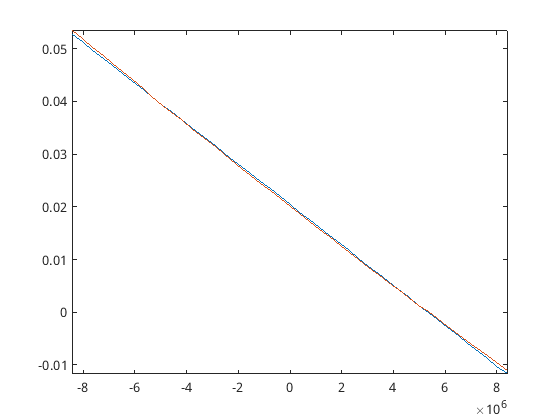

syms x
fplot(coeff(1)*x+coeff(2),[r_min r_max])
hold on
fplot(g,[r_min r_max])
hold off

1/-coeff(1)

ans = 2.6058e+08

vpa(ans)

$$ans = 260584752.22862055897712707519531$$